# **2108332 Adjustment Computation**

## **LAB 5** Observation equations

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

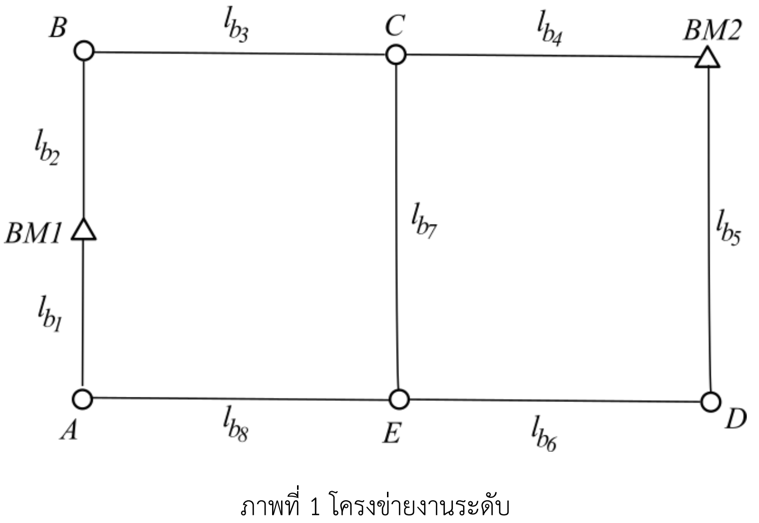

ภาพที่ 1 แสดงการรังวัดโครงข่ายงานระดับ ลูกศรในภาพแสดงถึงทิศทางการรังวัด ผลการรังวัดแสดงในตารางต่อไปนี้

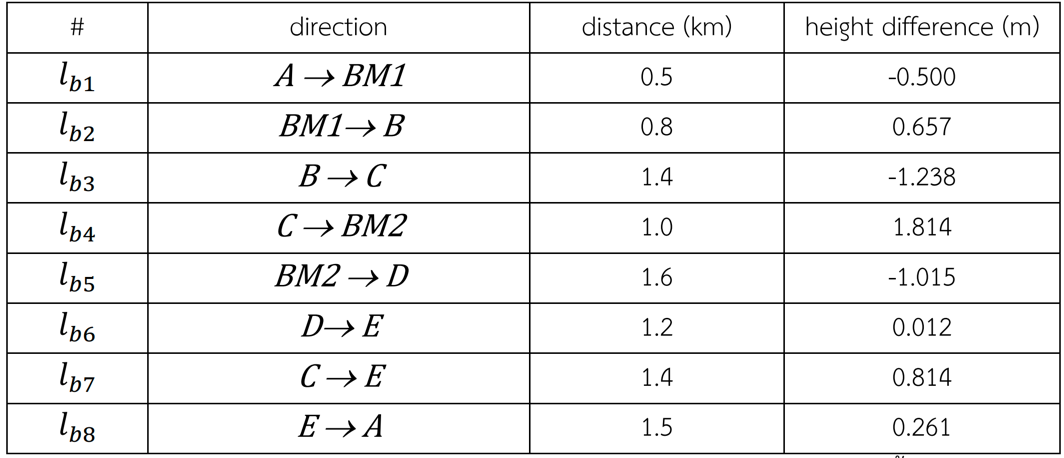

#### ค่าความสูงของจุด $BM1$ และ $BM2$ คือ 29.499 ม. และ 30.737 ม. ตามลำดับ กำหนดให้น้ำหนักของค่ารังวัดแต่ละค่าเป็นอิสระต่อกัน และแปรผกผันกับระยะทาง ให้เขียนสคริปต์ MATLAB เพื่อปรับแก้ค่ารังวัดโดยวิธีกำลังสองน้อยที่สุดแบบใช้สมการค่ารังวัด (มีพารามิเตอร์) สคริปต์จะต้องแสดงค่ารังวัดที่ปรับแก้แล้ว และ ค่าระดับของจุด $A, B, C$ และ $D$ 

clear
format long g
BM1 = 29.499;
BM2 = 30.737;
lb = [-0.500;0.657;-1.238;1.814;-1.015;0.012;0.814;0.261];

A = [-1 0 0 0 0;
    0 1 0 0 0;
    0 -1 1 0 0;
    0 0 -1 0 0;
    0 0 0 1 0;
    0 0 0 -1 1;
    0 0 -1 0 1;
    1 0 0 0 -1];

L0 = [BM1;
    -BM1;
    0;
    BM2;
    -BM2;
    0;
    0;
    0;];

P = [1/0.5;1/0.8;1/1.4;1/1;1/1.6;1/1.2;1/1.4;1/1.5];
P_diagonal = diag(P);
L = L0 - lb;


Xa = -(A' * P_diagonal * A) \ (A' * P_diagonal * L)

Xa =           29.9985030409731
           30.157318822023
          28.9216267605634
          29.7231498079385
          29.7360121638924


L_a = A * Xa + L0

L_a =          -0.49950304097311
         0.658318822023048
         -1.23569206145967
          1.81537323943662
         -1.01385019206147
        0.0128623559539029
         0.814385403329059
         0.262490877080673


#### 2. ต้องการคำนวณหาค่าสัมประสิทธิ์โพลีโนเมียล

### 
$$y=\textrm{ax}+b$$


โดยการปรับแก้วิธีกำลังสองน้อยที่สุดแบบใช้สมการค่ารังวัด ข้อมูลแสดงในตารางต่อไปนี้

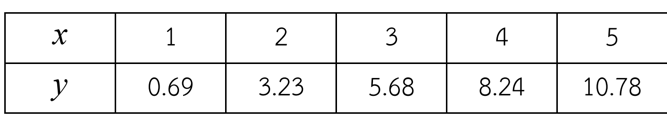

#### กำหนดให้ ค่าพิกัดทาง y เท่านั้นที่เป็นค่ารังวัด ส่วนค่าพิกัดทาง x เป็นค่าคงที่ ค่ารังวัดทั้งหมดเป็นอิสระต่อกัน โดยที่ $\sigma_1 =\sigma_3 =\sigma_5 =0\ldotp 05$ และ $\sigma_4 =\sigma_2 =0\ldotp 07$ ให้เขียนสคริปต์ MATLAB เพื่อปรับแก้ค่ารังวัด สคริปต์จะต้องแสดงค่าสัมประสิทธิ์โพลีโนเมียล และค่ารังวัดที่ปรับแก้แล้ว 

clear
format long g
P = [0.05^2;0.07^2;0.05^2;0.07^2;0.05^2];
P_diagonal = diag(P);
lb = [0.69;3.23;5.68;8.24;10.78];
L0 = [0;0;0;0;0];
L = L0 - lb;
A = [1 1;
    2 1;
    3 1;
    4 1;
    5 1];
Xa = -(A' * P_diagonal * A) \ (A' * P_diagonal * L)

Xa =           2.51674496644295
         -1.82318287620747


La = A * Xa + L0

La =          0.693562090235484
          3.21030705667844
          5.72705202312139
          8.24379698956434
          10.7605419560073
